# Linear boundary value problems for multidimensional equations

## Taks 1

% Розв'язування лінійної крайової задачі для двовимірного
% рівняння параболічного типу за допомогою ЛОС (ваги = 0.5)

% параметри задачі :
a1 = 1; a2 = 2;
% параметри різницевої схеми:
Nx = 21; Nx1 = Nx - 1; x = linspace(0, a1, Nx); hx = x(2) - x(1);
Ny = 41; Ny1 = Ny - 1; y = linspace(0, a2, Ny); hy = y(2) - y(1);
tau = 5e-2; M = 100;
% обчислення додаткових констант :
tau2 = 0.5 .* tau;
gsx = tau2 ./ (hx .* hx); gs2x = 2 .* gsx; ckx = 1 + gs2x;
gsy = tau2 ./ (hy .* hy); gs2y = 2 .* gsy; cky = 1 + gs2y;

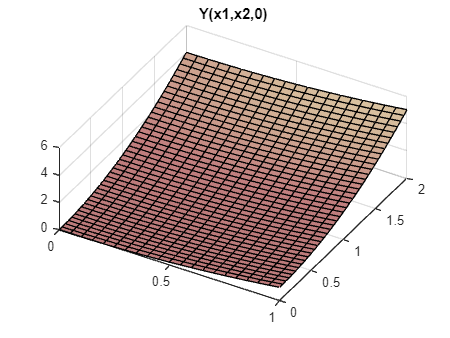

% формування початкових умов при t=0 :
Y = zeros(Nx, Ny);
for k1 = 1 : Nx
    xx = x(k1);
    for k2 = 1 : Ny
        Y(k1,k2) = t73_u0(xx,y(k2));
    end
end

% побудова графіків розв'язку при t=0 :
t = 0; Uview(t, x, y, Y, 'Y');

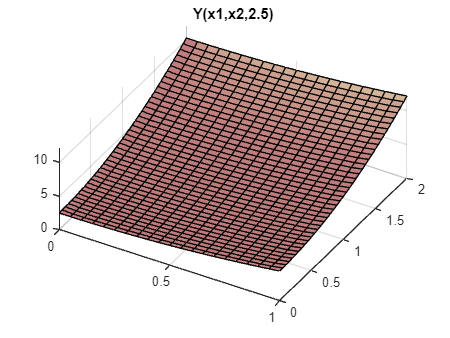


% формування постійних складових матриць СЛАР :
Ax = zeros(Nx, 1); Cx = ones(Nx, 1); Bx = Ax; Fx = Ax;
for k1 = 2 : Nx1
    Ax(k1) = gsx; Cx(k1) = ckx; Bx(k1) = gsx;
end

Ay = zeros(Ny, 1); Cy = ones(Ny, 1); By = Ay; Fy = Ay;
for k2 = 2 : Ny1
    Ay(k2) = gsy; Cy(k2) = cky; By(k2) = gsy;
end

ckx = 1 - gs2x; cky = 1 - gs2y;
for j = 1 : M
    % знаходження наближеного розв'язку Y на шарі t=t(j)-tau/2 :
    t = j .* tau; tt = t - tau2;
    YJ = Y;
    % обчислення крайових умов :
    for k1 = 1 : Nx
        xx = x(k1);
        Y(k1,1) = t73_mjx0(xx, tt); Y(k1,Ny) = t73_mjx1(xx, tt);
    end

    for k2 = 2 : Ny1
        yy = y(k2);
        Y(1,k2) = t73_mj0y(yy, tt); Y(Nx,k2) = t73_mj1y(yy, tt);
    end

    clear YY alfa

    for k2 = 2 : Ny1
        yy = y(k2);
        % формування СЛАР :
        Fx(1) = Y(1,k2); Fx(Nx) = Y(Nx,k2);
        for k1 = 2 : Nx1
            z = gsx .* (YJ(k1-1,k2) + YJ(k1+1,k2)) + ckx .* YJ(k1,k2);
            Fx(k1) = z + tau .* t73_f1(x(k1), yy, tt);
        end
        % розв'язок СЛАР, знаходження Y(:,k2) :
        [YY, alfa] = m_progn(Ax, Cx, Bx, Fx);
        Y(:,k2) = YY';
    end

    % знаходження наближеного розв'язку Y на шарі t=t(j) :
    YJ = Y;

    % обчислення крайових умов :
    for k1 = 1 : Nx
        xx = x(k1);
        Y(k1,1) = t73_mjx0(xx, t); Y(k1,Ny) = t73_mjx1(xx, t);
    end
    for k2 = 2 : Ny1
        yy = y(k2);
        Y(1,k2) = t73_mj0y(yy, t); Y(Nx,k2) = t73_mj1y(yy, t);
    end

    clear YY alfa

    for k1 = 2 : Nx1
        xx = x(k1);
        % формування СЛАР :
        Fy(1) = Y(k1,1); Fy(Ny) = Y(k1,Ny);
        for k2 = 2 : Ny1
            z = gsy .* (YJ(k1,k2-1) + YJ(k1,k2+1)) + cky .* YJ(k1,k2);
            Fy(k2) = z + tau .* t73_f2(xx, y(k2), tt);
        end
        % розв'язок СЛАР, знаходження Y(k1,:) :
        [YY, alfa] = m_progn(Ay, Cy, By, Fy);
        Y(k1,:) = YY';
    end
    if j * 2 == M % побудова графіка розв'язку при t=M*tau/2 :
        Uview(t, x, y, Y, 'Y');
    end
end

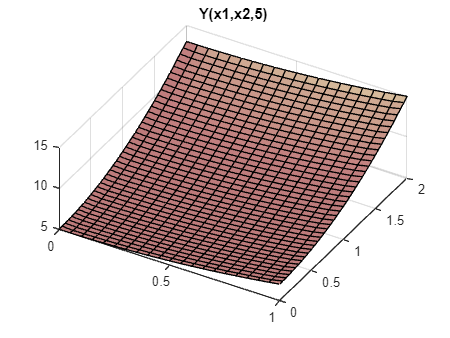


% побудова графіка розв'язку при M*tau :
Uview(t, x, y, Y, 'Y');

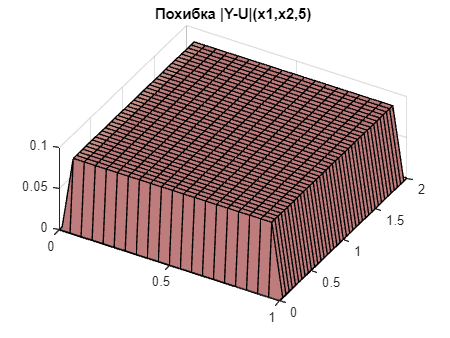

clear YY alfa Ax Cx Bx Fx Ay Cy By Fy YJ

% порівняння точного розв'язку U(x1,x2,t)=t+(2-exp(-t))(x1^2+x2^2)
% і наближеного Y в точці t=M*tau :
zz = 0;
for k1 = 1 : Nx
    xx = x(k1); xx = xx .* xx;
    for k2 = 1 : Ny
        yy = y(k2); yy = yy .* yy;
        z = t + (2 - exp(-t)) .* (xx + yy);
        z = abs(Y(k1,k2) - z);

        if z > zz
            zz = z;
        end

        Y(k1,k2) = z;
    end
end
Uview(t, x, y, Y, 'Похибка |Y-U|');

disp(strcat('Похибка: ||Y-U||c =',num2str(zz)))

Похибка: ||Y-U||c =0.087948


function z = Uview(t, x, y, U, name)
    [Yy, Xx] = meshgrid(y, x);
    surfl(Xx, Yy, U);
    z = num2str(t);
    title(strcat(name,'(x1,x2,',z,')'));
    colormap(pink), view(30,60);
end

function [y, alfa]  =  m_progn(a, c, b, f)  
    n = length(c); n1 = n - 1; 
    % пряма прогонка: 
    alfa = zeros(1, n); y = alfa; 
    beta = alfa; ka = ones(1, n); te = alfa; 
    C = c(1); A = a(2); F = f(1); Q = f(2); 
    for k = 1 : n1 
        j = k + 1; 
        if abs(C) >= abs(b(k)) 
            alfa(j) = b(k) ./ C; beta(j) = F ./ C; 
            C = c(j) - A .* alfa(j); F = Q + A .* beta(j); 
            te(j) = ka(k); ka(j) = j; 
            if k ~= n1 
                j = j + 1; A = a(j); Q = f(j); 
            end 
        else 
            alfa(j) = C ./ b(k); beta(j) = -F ./ b(k); 
            C = c(j) .* alfa(j) - A; F = Q - c(j) .* beta(j); 
            te(j) = j; ka(j) = ka(k); 
            if k ~= n1 
                j1 = j; j = j + 1; 
                A = a(j) .* alfa(j1); Q = f(j) + a(j) .* beta(j1); 
            end 
        end   
    end 
    % зворотня прогонка: 
    y(ka(n)) =F ./ C; 
    for k=n1 : -1 : 1 
        j = k + 1; y(te(j)) = alfa(j) .* y(ka(j)) + beta(j); 
    end 
end 

function u = t73_f1(x1,x2,t)
u = exp(-t).*(4+x1.^2);
end

function u = t73_f2(x1,x2,t)
u = exp(-t).*(x2.^2)-7;
end

function u = t73_mj0y(x,t)
u = t+x.^2.*(2-exp(-t));
end

function u = t73_mj1y(x,t)
u = t+(1+x.^2).*(2-exp(-t));
end

function u = t73_mjx0(x,t)
u = t+x.^2.*(2-exp(-t));
end

function u = t73_mjx1(x,t)
u = t+(x.^2+4).*(2-exp(-t));
end

function u = t73_u0(x1,x2)
u = x1.^2.+x2.^2;
end